# Emmanuelle Chaigneau

# Serge Charpak Laboratory

# Figure 7 Dual color ratioing

## Parameters

Fig7TitleFontsize = 14 ;
Fig7LegendFontsize = 10 ;
Fig7AxisLabelFontsize = 12 ;
Fig7Linewidth = 2 ;

Figure7 = figure;
Figure7.Position = [10 10 900 500] ;
Figure7Layout = tiledlayout(2,4);
Figure7Layout.Padding = 'tight';

## Set concentrations and depth

CA = 1.14 * 10^-5 ;
CB = 2 * 10^-5 ;

z = 0 : 1 : 50 ;


## Load and set spectral information

load('Lambda_MuAArtery.mat');
LambdaMuA = Lambda_MuAArtery(:,1);
MuAArt = Lambda_MuAArtery(:,2);

load('Lambda_MuAVein.mat');
MuAVein = Lambda_MuAVein(:,2);

load('Lambda_MupsBrain.mat') ;
MupsBrain = Lambda_MupsBrain(:,2) ;

load('Lambda_Phi_TexasRed.mat');
LambdaPhiNAS = Lambda_Phi_TexasRed(:,1);
PhiNAS = Lambda_Phi_TexasRed(:,2) / sum (Lambda_Phi_TexasRed(:,2));

load('Lambda_Phi_FITC.mat');
LambdaPhiNB = Lambda_Phi_FITC(:,1);
PhiNB = Lambda_Phi_FITC(:,2) / sum (Lambda_Phi_FITC(:,2));

Lambda1 = 500 ;
Lambda2 = 550 ;
Lambda3 = 578 ;
Lambda4 = 640 ;

SigmaN = 110 / 18 ;    


## Get values of interest

BooIdxMuALambda1to2 = logical( (LambdaMuA >= Lambda1) .* (LambdaMuA <= Lambda2) ) ;
BooIdxMuALambda3to4 = logical( (LambdaMuA >= Lambda3) .* (LambdaMuA <= Lambda4) ) ;

BooIdxASLambda3to4 = logical( (LambdaPhiNAS >= Lambda3) .* (LambdaPhiNAS <= Lambda4) ) ;

BooIdxBLambda1to2 = logical( (LambdaPhiNB >= Lambda1) .* (LambdaPhiNB <= Lambda2) ) ;
BooIdxBLambda3to4 = logical( (LambdaPhiNB >= Lambda3) .* (LambdaPhiNB <= Lambda4) ) ;


## Panel A1

## Venule sketch

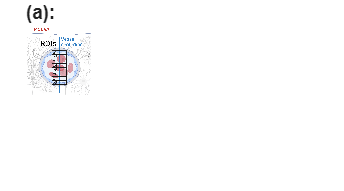

PanelA1 = nexttile([1 1]) ;

Sketch7A1 = imread('Fig 7 Large Blood vessel zscan center ROIs Venule.png');
image(Sketch7A1)

PanelA1.YColor = [1 1 1] ;
PanelA1.XColor = [1 1 1] ;

title('(a):', 'FontSize', Fig7TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel A2

## Artery sketch

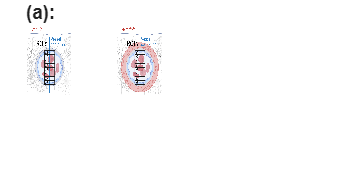

PanelA2 = nexttile([1 1]) ;

Sketch7A2 = imread('Fig 7 Large Blood vessel zscan center ROIs Arteriole.png');

image(Sketch7A2)

PanelA2.YColor = [1 1 1] ;
PanelA2.XColor = [1 1 1] ;

## Panel B

## Arteries results

nexttile([1 2])


### Load data 

load FRatioVsDepth_ArteriesAndVeins.mat

Depth = FRatioVsDepth_ArteriesAndVeins(:,1) ;

FRatioCenter_Arteries = FRatioVsDepth_ArteriesAndVeins(:, [2 4 6 7 9]) ;
FRatioCenter_Veins = FRatioVsDepth_ArteriesAndVeins(:, [3 5 8 10]) ;

AvgFRatioCenter_Veins = mean(FRatioCenter_Veins, 2, 'omitnan') ;
StdFRatioCenter_Veins = std(FRatioCenter_Veins, 0, 2, 'omitnan') ;


### Art1

FRatioCenter_Art1 = FRatioCenter_Arteries(:, 1) ;


### Art2

FRatioCenter_Art2 = FRatioCenter_Arteries(:, 2) ;

[AeOptArt2, SumResidualsAeOptArt2, R2AeOptArt2] = FindAeOptAbScModelPhi(0.69, MuAArt, MupsBrain, Depth(:), PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2, CA, CB, SigmaN, ...
    FRatioCenter_Art2 )

Difftest =     0.0505
    0.0766
    0.1092
    0.1481
    0.1932
    0.2440
    0.3003
    0.3619
    0.4283
    0.4993
    0.5744
    0.6535
    0.7362
    0.8221
    0.9109


AeOptArt2 = 1

SumResidualsAeOptArt2 = 0.0505

R2AeOptArt2 = 0.8466


[PhiAS34AeOptArt2, PhiB34AeOptArt2, PhiB12AeOptArt2] = TricoliCoefs1234Phi(AeOptArt2, 0.69, MuAArt, MupsBrain, z, PhiNAS, PhiNB, ... 
    BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelArt2 = CA * SigmaN / CB * PhiAS34AeOptArt2 ./ PhiB12AeOptArt2 + ...
    PhiB34AeOptArt2 ./ PhiB12AeOptArt2 ;


### Art3

FRatioCenter_Art3 = FRatioCenter_Arteries(:, 3) ;

[AeOptArt3, SumResidualsAeOptArt3, R2AeOptArt3] = FindAeOptAbScModelPhi(0.69, MuAArt, MupsBrain, Depth(:), PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2, CA, CB, SigmaN, ...
    FRatioCenter_Art3 )

Difftest =     0.1713
    0.1274
    0.0904
    0.0601
    0.0365
    0.0193
    0.0084
    0.0035
    0.0045
    0.0110
    0.0227
    0.0394
    0.0608
    0.0866
    0.1164


AeOptArt3 = 1.3500

SumResidualsAeOptArt3 = 0.0035

R2AeOptArt3 = 0.9681


[PhiAS34AeOptArt3, PhiB34AeOptArt3, PhiB12AeOptArt3] = TricoliCoefs1234Phi(AeOptArt3, 0.69, MuAArt, MupsBrain, z, PhiNAS, PhiNB, ... 
    BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelArt3 = CA * SigmaN / CB * PhiAS34AeOptArt3 ./ PhiB12AeOptArt3 + ...
    PhiB34AeOptArt3 ./ PhiB12AeOptArt3 ;


### Art4

FRatioCenter_Art4 = FRatioCenter_Arteries(:, 4) ;


### Art5

FRatioCenter_Art5 = FRatioCenter_Arteries(:, 5) ;


### Plot results 

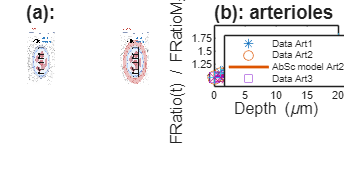

hDatazArt1 = plot(Depth(:), FRatioCenter_Art1,'*');
hold on
hDatazArt2 = plot(Depth(:), FRatioCenter_Art2,'o');
hAbScModelArt2 = plot (z, FRatioAbScModelArt2 / FRatioAbScModelArt2(1), '-') ;
hDatazArt3 = plot(Depth(:), FRatioCenter_Art3,'square');
hAbScModelArt3 = plot (z, FRatioAbScModelArt3 / FRatioAbScModelArt3(1), '-') ;
hDatazArt4 = plot(Depth(:), FRatioCenter_Art4,'+');
hDatazArt5 = plot(Depth(:), FRatioCenter_Art5,'x');
hold off

hDatazArt1.MarkerSize = 10 ;
hDatazArt2.MarkerSize = 10 ;
hAbScModelArt2.LineWidth = Fig7Linewidth  ;
hAbScModelArt2.Color = hDatazArt2.Color ;
hDatazArt3.MarkerSize = 10 ;
hAbScModelArt3.LineWidth = Fig7Linewidth  ;
hAbScModelArt3.Color = hDatazArt3.Color ;
hDatazArt4.MarkerSize = 10 ;
hDatazArt5.MarkerSize = 10 ;

legend('Data Art1', 'Data Art2', 'AbSc model Art2', 'Data Art3', 'AbSc model Art3', ...
    'Data Art4', 'Data Art5', 'Location', 'NorthWest', 'numcolumns', 2);
xlabel("Depth (\mum)", "FontSize", Fig7AxisLabelFontsize) ;
ylabel("FRatio(t) / FRatioM_{z=0}(t)", "FontSize", Fig7AxisLabelFontsize) ;
axis([0 20 0.82 2]);
xticks([0 5 10 15 20]);
yticks([1 1.25 1.5 1.75]);

title('(b): arterioles', 'FontSize', Fig7TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel C

## Veins

nexttile([1 2])


### Fit indiv veinules with AbSc model

### Vein1

FRatioCenter_Vein1 = FRatioCenter_Veins(:, 1) ;

[AeOptVein1, SumResidualsAeOptVein1, R2AeOptVein1] = FindAeOptAbScModelPhi(0.69, MuAVein, MupsBrain, Depth(1:21), PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2, CA, CB, SigmaN, ...
    FRatioCenter_Vein1 )

Difftest =     0.0227
    0.0201
    0.0214
    0.0264
    0.0351
    0.0472
    0.0626
    0.0809
    0.1019
    0.1255
    0.1515
    0.1795
    0.2095
    0.2412
    0.2745


AeOptVein1 = 1.0500

SumResidualsAeOptVein1 = 0.0201

R2AeOptVein1 = 0.8900


[PhiAS34AeOptVein1, PhiB34AeOptVein1, PhiB12AeOptVein1] = TricoliCoefs1234Phi(AeOptVein1, 0.69, MuAVein, MupsBrain, z, PhiNAS, PhiNB, ... 
    BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelVein1 = CA * SigmaN / CB * PhiAS34AeOptVein1 ./ PhiB12AeOptVein1 + ...
    PhiB34AeOptVein1 ./ PhiB12AeOptVein1 ;


### Vein2

FRatioCenter_Vein2 = FRatioCenter_Veins(1:19, 2) ;

[AeOptVein2, SumResidualsAeOptVein2, R2AeOptVein2] = FindAeOptAbScModelPhi(0.69, MuAVein, MupsBrain, Depth(1:19), PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2, CA, CB, SigmaN, ...
    FRatioCenter_Vein2 )

Difftest =     0.1307
    0.1052
    0.0829
    0.0638
    0.0478
    0.0349
    0.0249
    0.0177
    0.0131
    0.0112
    0.0116
    0.0144
    0.0192
    0.0261
    0.0348


AeOptVein2 = 1.4500

SumResidualsAeOptVein2 = 0.0112

R2AeOptVein2 = 0.6150


[PhiAS34AeOptVein2, PhiB34AeOptVein2, PhiB12AeOptVein2] = TricoliCoefs1234Phi(AeOptVein2, 0.69, MuAVein, MupsBrain, z, PhiNAS, PhiNB, ... 
    BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelVein2 = CA * SigmaN / CB * PhiAS34AeOptVein2 ./ PhiB12AeOptVein2 + ...
    PhiB34AeOptVein2 ./ PhiB12AeOptVein2 ;


### Vein3

FRatioCenter_Vein3 = FRatioCenter_Veins(1:17, 3) ;

[AeOptVein3, SumResidualsAeOptVein3, R2AeOptVein3] = FindAeOptAbScModelPhi(0.69, MuAVein, MupsBrain, Depth(1:17), PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2, CA, CB, SigmaN, ...
    FRatioCenter_Vein3 )

Difftest =     0.0131
    0.0199
    0.0289
    0.0400
    0.0532
    0.0684
    0.0854
    0.1042
    0.1247
    0.1468
    0.1703
    0.1953
    0.2214
    0.2488
    0.2771


AeOptVein3 = 1

SumResidualsAeOptVein3 = 0.0131

R2AeOptVein3 = 0.8897


[PhiAS34AeOptVein3, PhiB34AeOptVein3, PhiB12AeOptVein3] = TricoliCoefs1234Phi(AeOptVein3, 0.69, MuAVein, MupsBrain, z, PhiNAS, PhiNB, ... 
    BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelVein3 = CA * SigmaN / CB * PhiAS34AeOptVein3 ./ PhiB12AeOptVein3 + ...
    PhiB34AeOptVein3 ./ PhiB12AeOptVein3 ;


### Vein4

FRatioCenter_Vein4 = FRatioCenter_Veins(:, 4) ;

[AeOptVein4, SumResidualsAeOptVein4, R2AeOptVein4] = FindAeOptAbScModelPhi(0.69, MuAVein, MupsBrain, Depth(:), PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2, CA, CB, SigmaN, ...
    FRatioCenter_Vein4 )

Difftest =     0.0453
    0.0323
    0.0233
    0.0182
    0.0167
    0.0188
    0.0242
    0.0326
    0.0440
    0.0581
    0.0746
    0.0934
    0.1143
    0.1371
    0.1616


AeOptVein4 = 1.2000

SumResidualsAeOptVein4 = 0.0167

R2AeOptVein4 = 0.9078


[PhiAS34AeOptVein4, PhiB34AeOptVein4, PhiB12AeOptVein4] = TricoliCoefs1234Phi(AeOptVein4, 0.69, MuAVein, MupsBrain, z, PhiNAS, PhiNB, ... 
    BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelVein4 = CA * SigmaN / CB * PhiAS34AeOptVein4 ./ PhiB12AeOptVein4 + PhiB34AeOptVein4 ./ PhiB12AeOptVein4 ;


### Plot results

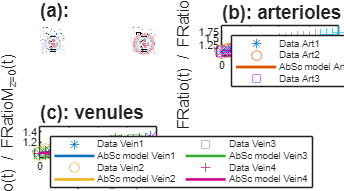

hDatazVein1 = plot(Depth(1:21), FRatioCenter_Vein1,'*');
hold on
hAbScModelVein1 = plot (z, FRatioAbScModelVein1 / FRatioAbScModelVein1(1), '-') ;
hDatazVein2 = plot(Depth(1:19), FRatioCenter_Vein2,'o');
hAbScModelVein2 = plot (z, FRatioAbScModelVein2 / FRatioAbScModelVein2(1), '-') ;
hDatazVein3 = plot(Depth(1:17), FRatioCenter_Vein3,'square');
hAbScModelVein3 = plot (z, FRatioAbScModelVein3 / FRatioAbScModelVein3(1), '-') ;
hDatazVein4 = plot(Depth(:), FRatioCenter_Vein4,'+') ;
hAbScModelVein4 = plot (z, FRatioAbScModelVein4 / FRatioAbScModelVein4(1), '-') ;
hold off

hDatazVein1.MarkerSize = 10 ;
hAbScModelVein1.LineWidth = Fig7Linewidth  ;
hAbScModelVein1.Color = hDatazVein1.Color ;
hDatazVein2.MarkerSize = 10 ;
hAbScModelVein2.LineWidth = Fig7Linewidth  ;
hAbScModelVein2.Color = hDatazVein2.Color ;
hDatazVein3.MarkerSize = 10 ;
hAbScModelVein3.LineWidth = Fig7Linewidth  ;
hAbScModelVein3.Color = hDatazVein3.Color ;
hDatazVein4.MarkerSize = 10 ;
hAbScModelVein4.LineWidth = Fig7Linewidth  ;
hAbScModelVein4.Color = hDatazVein4.Color ;

legend('Data Vein1', 'AbSc model Vein1', 'Data Vein2', 'AbSc model Vein2', 'Data Vein3', 'AbSc model Vein3', ...
    'Data Vein4', 'AbSc model Vein4', 'Location', 'NorthWest', 'numcolumns', 2);
xlabel("Depth (\mum)", "FontSize", Fig7AxisLabelFontsize)
ylabel("FRatio(t) / FRatioM_{z=0}(t)", "FontSize", Fig7AxisLabelFontsize)
axis([0 20 0.92 1.5]);
xticks([0 5 10 15 20]);
yticks([1 1.2 1.4]);

title('(c): venules', 'FontSize', Fig7TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel d

## Average veins + fits 

nexttile([1 2])


### AbSc model

[AeOptVein, SumResidualsAeOptVein, R2AeOptVein] = FindAeOptAbScModelPhi(0.69, MuAVein, MupsBrain, Depth(1:19), PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2, CA, CB, SigmaN, ...
    AvgFRatioCenter_Veins(1:19) )

Difftest =     0.0185
    0.0101
    0.0049
    0.0026
    0.0032
    0.0066
    0.0126
    0.0212
    0.0321
    0.0452
    0.0604
    0.0775
    0.0964
    0.1170
    0.1390


AeOptVein = 1.1500

SumResidualsAeOptVein = 0.0026

R2AeOptVein = 0.9712


[PhiAbSc34AeOptVein, ThetaAbSc34AeOptVein, Sum12AeOptVein] = TricoliCoefs1234Phi(AeOptVein, 0.69, MuAVein, MupsBrain, ...
    z, PhiNAS, PhiNB, BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, ...
    BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelVein = CA * SigmaN / CB * PhiAbSc34AeOptVein ./ Sum12AeOptVein + ThetaAbSc34AeOptVein ./ Sum12AeOptVein ;


### Ab model

N34DivN12zAbModelVein = sum(PhiNAS(BooIdxASLambda3to4).*exp(-MuAVein(BooIdxMuALambda3to4)*z)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-MuAVein(BooIdxMuALambda1to2)*z)) ...
          + sum(PhiNB(BooIdxBLambda3to4).*exp(-MuAVein(BooIdxMuALambda3to4)*z)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-MuAVein(BooIdxMuALambda1to2)*z));

AbModelBVdataDepthVein = sum(PhiNAS(BooIdxASLambda3to4).*exp(-MuAVein(BooIdxMuALambda3to4)*Depth')) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-MuAVein(BooIdxMuALambda1to2)*Depth')) ...
          + sum(PhiNB(BooIdxBLambda3to4).*exp(-MuAVein(BooIdxMuALambda3to4)*Depth')) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-MuAVein(BooIdxMuALambda1to2)*Depth'));

SumResidualsAbModelVein = sum((AvgFRatioCenter_Veins(1:21) - ( AbModelBVdataDepthVein(1:21) / AbModelBVdataDepthVein(1))').^2)

SumResidualsAbModelVein = 0.0121


R2AbModelVein = 1- (sum((AvgFRatioCenter_Veins(1:21) - ( AbModelBVdataDepthVein(1:21) / AbModelBVdataDepthVein(1))').^2) / ...
   sum((AvgFRatioCenter_Veins(1:21) - mean(AvgFRatioCenter_Veins(1:21))).^2 )  ) 

R2AbModelVein = 0.9091

### Plot results

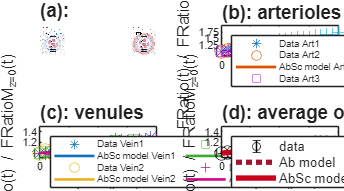

hDatazVein = errorbar(Depth(1:19), AvgFRatioCenter_Veins(1:19), StdFRatioCenter_Veins(1:19), 'ko') ;
hold on
hAbModelVein = plot (z, N34DivN12zAbModelVein / N34DivN12zAbModelVein(1), ':') ;
hAbScModelVein = plot (z, FRatioAbScModelVein / FRatioAbScModelVein(1), '-') ;
hold off

hDatazVein.MarkerSize = 10 ;
hAbModelVein.LineWidth = Fig7Linewidth *2 ;
hAbModelVein.Color = [0.6350 0.0780 0.1840] ;
hAbScModelVein.LineWidth = Fig7Linewidth *2 ;
hAbScModelVein.Color = [0.8 0 0.1] ;

legend('data', 'Ab model', 'AbSc model Opt', 'Location', 'NorthWest', "FontSize", Fig7LegendFontsize, ...
    'Location', 'NorthWest');
xlabel("Depth (\mum) ","FontSize", Fig7AxisLabelFontsize)
ylabel("FRatio(t) / FRatioM_{z=0}(t)", "FontSize", Fig7AxisLabelFontsize)
axis([0 20 0.92 1.5]);
xticks([0 5 10 15 20]);
yticks([1 1.2 1.4]);

title('(d): average over venules', 'FontSize', Fig7TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';